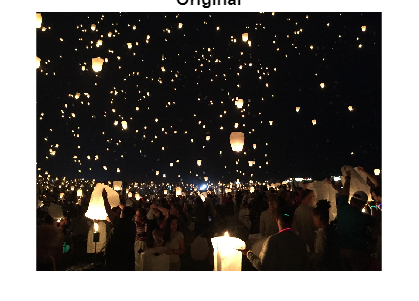

img = imread("FlyingLanterns.jpg");
imshow(img)
title("Original")

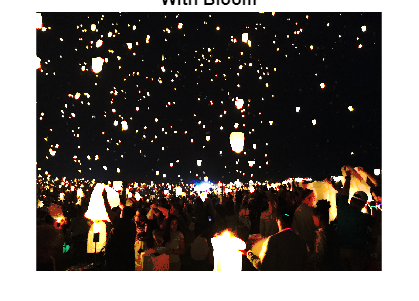

result = addBloom(img,0.4,50);
imshow(result)
title("With Bloom")

function bloom_image = addBloom(img, strength, threshold)

% Convert image to double precision for calculations
img = double(img);

% Create blurred versions of the image with different Gaussian filters
blur1 = imgaussfilt(img, 2);
blur2 = imgaussfilt(img, 5);
blur3 = imgaussfilt(img, 10);

% Extract bright pixels exceeding the threshold
bright_pixels = (img > threshold);

% Combine blurred versions weighted by strength
bloom = (strength * blur3) + ((1 - strength) * blur2) + (0.5 * blur1);

% Apply bloom only to bright pixels
bloom = bloom .* bright_pixels;

% Add bloom to the original image
bloom_image = img + bloom;

% Convert back to uint8 range for display
bloom_image = uint8(bloom_image);

end